# **Arbeiten in der Wissenschaft**

# Min, Max, Mean - LIVE Session 

## 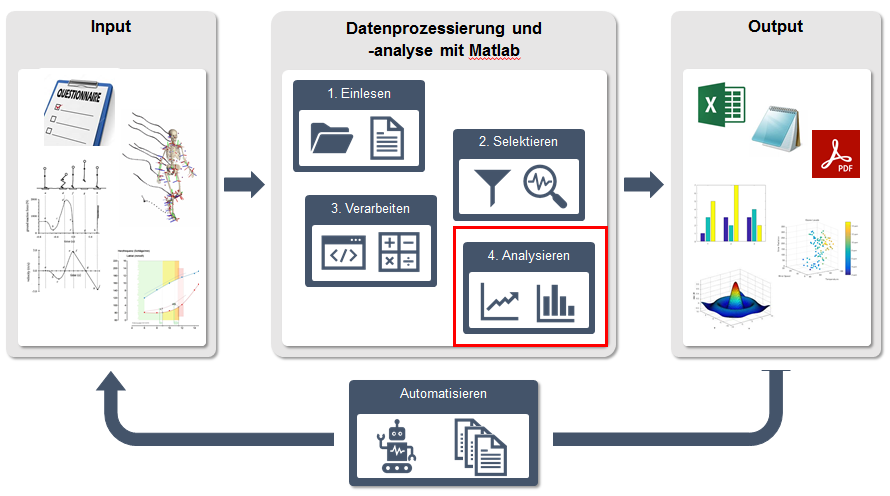

## Review der gelernten Inhalte

- Aufgabe 1: Laktat: *max, min, plot*

- Aufgabe 2*: *Laktat: *mean, omitnan, LineWidth*

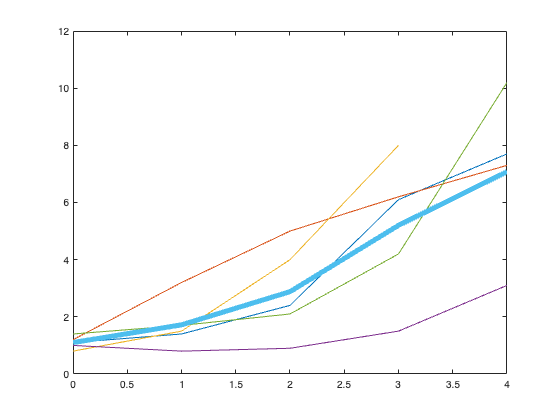

% Aufagbe 2
clc; clear; close all
% Daten einlesen
Laktat = readtable('Laktat.xlsx');
Laktat = table2array(Laktat);

% Extrahieren der 5 Proband*innen aus Aufgabe 1
Tn1=Laktat(1,:); Tn2=Laktat(16,:); Tn3=Laktat(13,:); Tn4=Laktat(14,:); Tn5=Laktat(8,:);

% Speichern der Laktatwerte in einer Matrix 'A' und Mittelwertkurve berechnen
A = [Tn1; Tn2; Tn3; Tn4; Tn5];

% Matrix 'A' ohne "Messfehler"
meanLaktat = mean(A, 'omitnan');

% Plotten der Laktatkurven
Stufe = (0:4);
figure(1)
plot(Stufe, Tn1); 
hold on
plot(Stufe, Tn2);
plot(Stufe, Tn3);
plot(Stufe, Tn4);
plot(Stufe, Tn5);
plot(Stufe, meanLaktat, 'LineWidth',5)

## Vertiefung der bereits gelernten Inhalte

### Median berechnen 

Berechnung der Median Kurve und plotten in vorheriges Schaubild.

*Median ist bspw. robuster gegen Ausreiser; indiv. Abwaegung ob Mittelwert (mean) oder Median sinnvoll ist. *

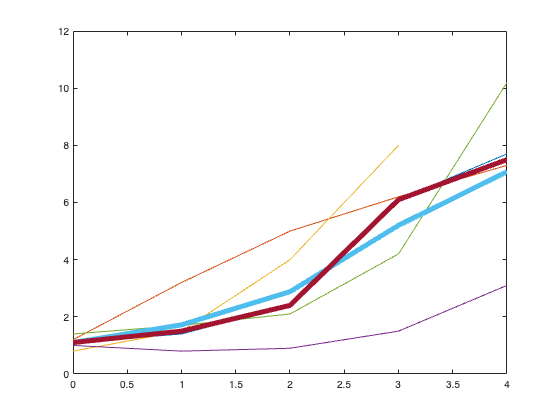

medianLaktat = median(A, 'omitnan');
plot(Stufe, medianLaktat, 'LineWidth', 5)

### Legende erstellen

Erstelle zusaetzlich eine Legende in der vorherigen Grafik.

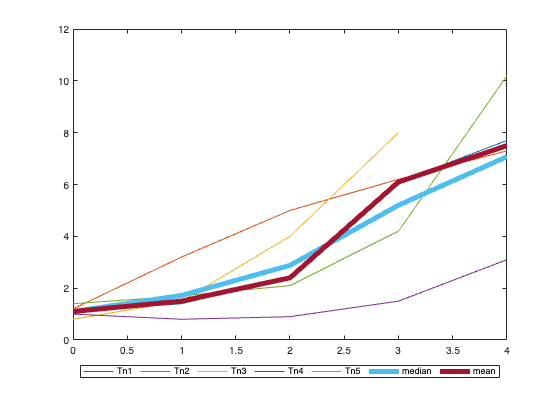

% Legende einblenden, Daten labeln, Reihenfolge beachten! und Position der Legende im Schaubild festlegen
legend ('Tn1', 'Tn2', 'Tn3', 'Tn4', 'Tn5', 'median', 'mean') 
% Location aendern -> 'Location', 'northwest'
legend ('Tn1', 'Tn2', 'Tn3', 'Tn4', 'Tn5', 'median', 'mean', 'Location', 'northwest') 
% Orientierung aendern -> 'Orientation', 'horizontal'
legend ('Tn1', 'Tn2', 'Tn3', 'Tn4', 'Tn5', 'median', 'mean', 'location', 'southoutside', 'orientation', 'horizontal') 
hold off

## Weiterfuehrende Inhalte

### Standardabweichung berechnen

Berechne die Standardabweichung der 5 Teilnehmer*innen fuer jede Stufe

Standardabw = std(A)

Standardabw =     0.2236    0.8927    1.6208    2.4668       NaN


**-> wie koennen wir hier mit 'NaN' umgehen? **

Standardabw = std(A, 'omitnan')

Standardabw =     0.2236    0.8927    1.6208    2.4668    2.9443


### k Minimum/Maximumwerte finden

Finde die 3 niedrigsten und die 3 hoechsten Werte der letzten Stufe der 5 Teilnehmer*innnen in Matrix 'Laktat'.

[Three_max_values, idx] = maxk(Laktat(:,5), 3)

Three_max_values =    10.2000
    9.8000
    9.8000


idx =      8
     3
    11


[Three_min_values, idx] = mink(Laktat(:,5),3)

Three_min_values =     3.1000
    4.7000
    4.8000


idx =     14
    15
    12


### Herzfrequenzdaten einer Smartwatch eines Intervall-Laufs analysieren

Intervalle: 10x2min schnelles Tempo, 1min Pause -> 30min Workout

Athlet: 27 Jahre

Ziel: 1. grafische Darstellung der Herzfrequenz  (HF)

        2. maximale HF & Zeitpunkt der maximalen HF pro Intervall 

% % Command window leeren, workspace leeren , figures schliessen
% clc; clear; close all 
% Daten einlesen
smartwatch_data = readtable("Intervalle_2021-01-04_16-12-29_X.csv")

smartwatch_data = 1750×11 table
    SampleRate      Time      HR_bpm_    Speed_km_h_    Pace_min_km_    Cadence    Altitude_m_    StrideLength_m_    Distances_m_    Temperatures_C_    Power_W_
    __________    ________    _______    ___________    ____________    _______    ___________    _______________    ____________    _______________    ________

         1        00:00:00       94            0         {'00:00'}         0           244              NaN                 0             11.2              0   
       NaN        00:00:01       90            0         {'00:00'}         0           244              NaN   

Die Daten sind folgendermassen strukturiert. 

- Die Zeit befindet sich in Spalte 2

- HF in Spalte 3

- 1 Messpunkt pro Sekunde (Aufnahmerate: 1Hz)

#### 1. grafische Darstellung der Herzfrequenz  

% extrahieren der HF Daten
HR = smartwatch_data(:,3);

% konvertieren des Tabellenformats in einen Vektor
HR = table2array(HR)

HR =     94
    90
    88
    85
    84
    82
    82
    82
    84
   103


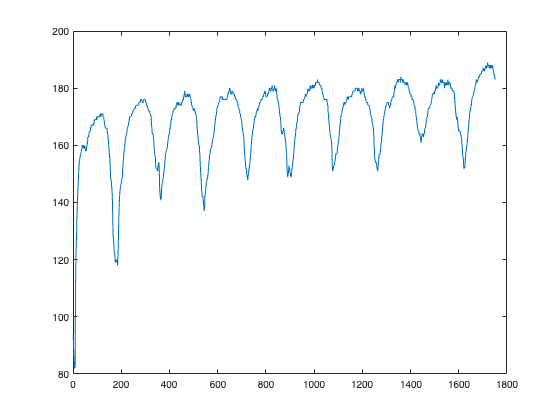

% Daten plotten
plot(HR)

#### 2. maximale Herzfrequenz pro Intervall 

Die Funktinon 'findpeaks' findet lokale Maxima in den Daten und kann diese plotten/kennzeichnen

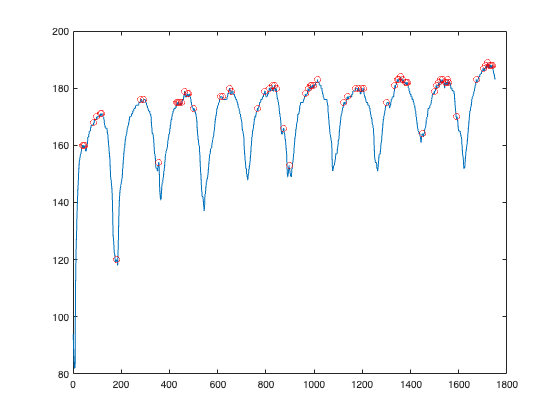

[peaks,locs] = findpeaks(HR);
plot(HR);
hold on;
plot(locs,peaks,'ro')
hold off 

_______________________________________________________________________________________

**! Ihr seid gefragt ! **

Spezifiziere die Funktion 'findpeaks' so, dass pro Intervall nur ein Peak gefunden wird

--> help findpeaks ODER doc findpeaks ODER Google: "Matlab findpeaks"

                                                    - 5-10min Zeit - 

_______________________________________________________________________________________

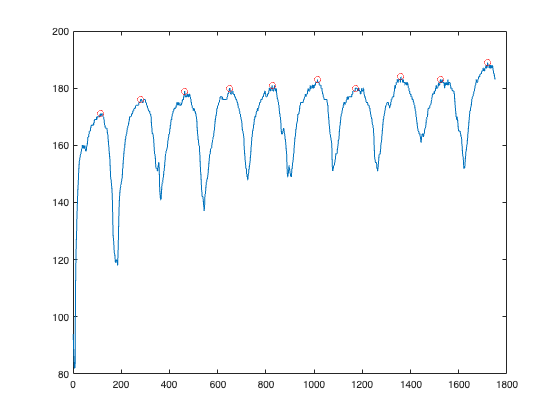

% Findet Peaks mit Mindestabstand von 150 Datenpunkten
[peaks, locs] = findpeaks(HR, 'MinPeakDistance', 150);

% Plotte die Herzfrequenz und markiere die Peaks
plot(HR);
hold on;
plot(locs, peaks, 'ro'); % Markiere die Peaks mit roten Punkten
hold off;


[max_HR,max_index] =max(peaks)

max_HR = 189

max_index = 10

time_of_max_HR = locs(max_index);
disp(['Maximum HR: ', num2str(max_HR)]);

Maximum HR: 189


disp(['Time of Maximum HR: ', num2str(time_of_max_HR)])

Time of Maximum HR: 1720


_______________________________________________________________________________________

**! Ihr seid gefragt ! **